# Train Object Detector Using R-CNN Deep Learning

## César Martín Guijarro & Pablo García García

Firstly, we'll download the dataset from the given URL. 

cifar10Data = tempdir;
url = 'https://www.cs.toronto.edu/~kriz/cifar-10-matlab.tar.gz';
helperCIFAR10Data.download(url, cifar10Data);

Then, we load the data: 

[trainingImages, trainingLabels, testImages, testLabels] = helperCIFAR10Data.load(cifar10Data);
disp(size(trainingImages)); 

          32          32           3       50000



Now we can check the different categories of the images: 

numImageCategories = 10;
disp(categories(trainingLabels)); 

    {'airplane'  }
    {'automobile'}
    {'bird'      }
    {'cat'       }
    {'deer'      }
    {'dog'       }
    {'frog'      }
    {'horse'     }
    {'ship'      }
    {'truck'     }



Let's see some of the images of the dataset: 

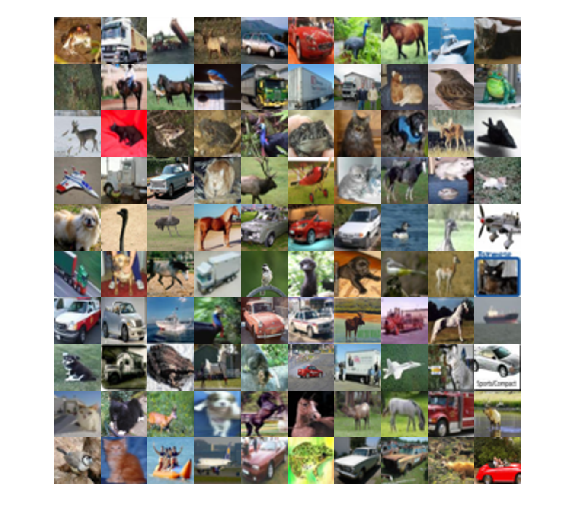

figure; 
thumbnails = trainingImages(:,:,:,1:100);
montage(thumbnails); 

Now we are going to create the CNN. Later, in out slide presentation we will explain how the CNN works. 

[height, width, numChannels, ~] = size(trainingImages);
imageSize = [height width numChannels];
inputLayer = imageInputLayer(imageSize)

inputLayer =   ImageInputLayer with properties:

                      Name: ''
                 InputSize: [32 32 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: []


filterSize = [5 5];
numFilters = 32;

middleLayers = [
    convolution2dLayer(filterSize, numFilters, 'Padding', 2)
    reluLayer()
    maxPooling2dLayer(3, 'Stride', 2)
    convolution2dLayer(filterSize, numFilters, 'Padding', 2)
    reluLayer()
    maxPooling2dLayer(3,'Stride', 2)
    convolution2dLayer(filterSize, 2 * numFilters, 'Padding', 2)
    reluLayer()
    maxPooling2dLayer(3, 'Stride', 2)
]; 

finalLayers = [
    fullyConnectedLayer(64)
    reluLayer
    fullyConnectedLayer(numImageCategories)
    softmaxLayer
    classificationLayer
]; 

layers = [
    inputLayer
    middleLayers
    finalLayers
]; 

layers(2).Weights = 0.0001 * randn([filterSize numChannels numFilters]);

Now we are able to train the net. We'll be using a NVIDIA GPU to make this process faster. 

opts = trainingOptions('sgdm', ...
    'Momentum', 0.9, ...
    'InitialLearnRate', 0.001, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', 8, ...
    'L2Regularization', 0.004, ...
    'MaxEpochs', 40, ...
    'MiniBatchSize', 128, ...
    'Verbose', true);

doTraining = true;
if doTraining    
    cifar10Net = trainNetwork(trainingImages, trainingLabels, layers, opts);
else
    load('rcnnStopSigns.mat','cifar10Net')       
end

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |        7.03% |       2.3061 |          0.0010 |
|       1 |          50 |       00:00:00 |       10.94% |       2.2952 |          0.0010 |
|       1 |         100 |       00:00:01 |       14.06% |       2.2498 |          0.0010 |
|       1 |         150 |       00:00:02 |       16.41% |       2.2107 |          0.0010 |
|       1 |         200 |       00:00:03 |       25.00% |       2.0651 |          0.0010 |
|       1 |         250 |       00:00:04 |       26.56% |       2.0542 |          0.0010 |
|       1 |         300 |  

Once the training has finished, we can see what is happening in some of the middle layers. In this case, it seems as it its trying to detect borders. 

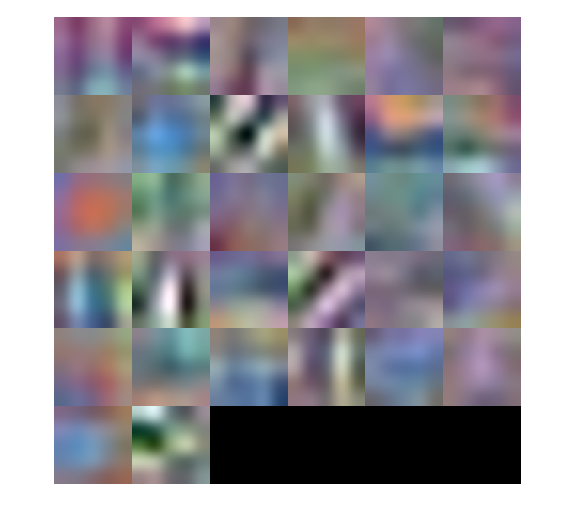

w = cifar10Net.Layers(2).Weights;
w = rescale(w);

figure
montage(w); 

Now we will check if the network has been trained correctly: 

YTest = classify(cifar10Net, testImages);
accuracy = sum(YTest == testLabels)/numel(testLabels)

accuracy = 0.6244

### Detecting STOP signs

Having correctly trained our CNN, we will try to use it to detect STOP signs. To do so, we need to load only the images we will use. 

data = load('stopSignsAndCars.mat', 'stopSignsAndCars');
stopSignsAndCars = data.stopSignsAndCars;

visiondata = fullfile(toolboxdir('vision'), 'visiondata');
stopSignsAndCars.imageFilename = fullfile(visiondata, stopSignsAndCars.imageFilename);

summary(stopSignsAndCars)

Variables:

    imageFilename: 41×1 cell array of character vectors

    stopSign: 41×1 cell

    carRear: 41×1 cell

    carFront: 41×1 cell



In this dataset, every object of interest has a bounding box surrounding it, so to detect stop signs we need to load only the images which them. Let's see an example of an image with an stop sign with its boundary box. 

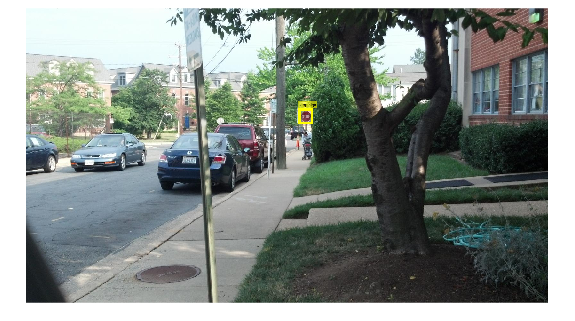

stopSigns = stopSignsAndCars(:, {'imageFilename','stopSign'});

I = imread(stopSigns.imageFilename{1});
I = insertObjectAnnotation(I,'Rectangle',stopSigns.stopSign{1},'stop sign','LineWidth',8);

figure
imshow(I)

Now we will train our CNN but not from 0 knowledge, it will be a training that modifies the knowledge of the CIFAR-10 network. 

doTraining = true;

if doTraining

    options = trainingOptions('sgdm', ...
        'MiniBatchSize', 128, ...
        'InitialLearnRate', 1e-3, ...
        'LearnRateSchedule', 'piecewise', ...
        'LearnRateDropFactor', 0.1, ...
        'LearnRateDropPeriod', 100, ...
        'MaxEpochs', 100, ...
        'Verbose', true);
  
    rcnn = trainRCNNObjectDetector(stopSigns, cifar10Net, options, ...
    'NegativeOverlapRange', [0 0.3], 'PositiveOverlapRange',[0.5 1]); 
else
    load('rcnnStopSigns.mat','rcnn');        
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.
*******************************************************************
Training an R-CNN Object Detector for the following object classes:

* stopSign

--> Extracting region proposals from 41 training images...done.

--> Training a neural network to classify objects in training data...

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       75.00% |       0.6819 |          0.0010 |
|       6 |          50 |       00:00:10 |       98.44% |       0.0813 |          0.001

As we've done before, once the training has finished, we can try the net. 

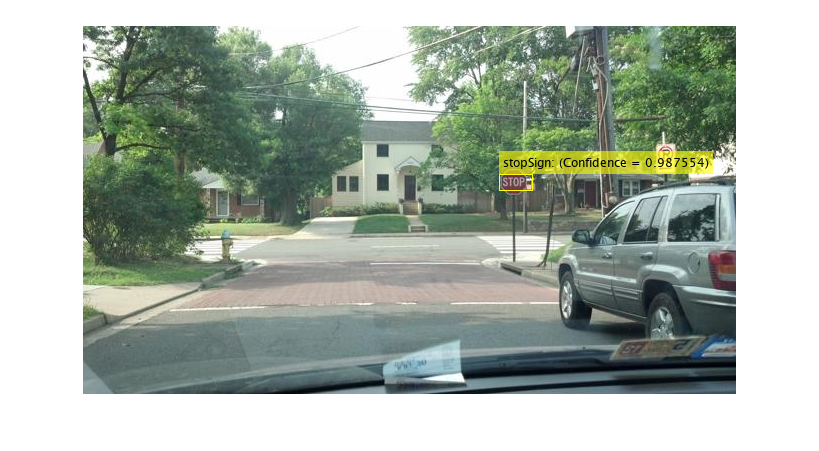

testImage = imread('stopSignTest.jpg');
[bboxes,score,label] = detect(rcnn, testImage, 'MiniBatchSize', 128); 

[score, idx] = max(score);

bbox = bboxes(idx, :);
annotation = sprintf('%s: (Confidence = %f)', label(idx), score);

outputImage = insertObjectAnnotation(testImage, 'rectangle', bbox, annotation);

figure; 
imshow(outputImage); 

Now we can try the model with some photos taken by us: 

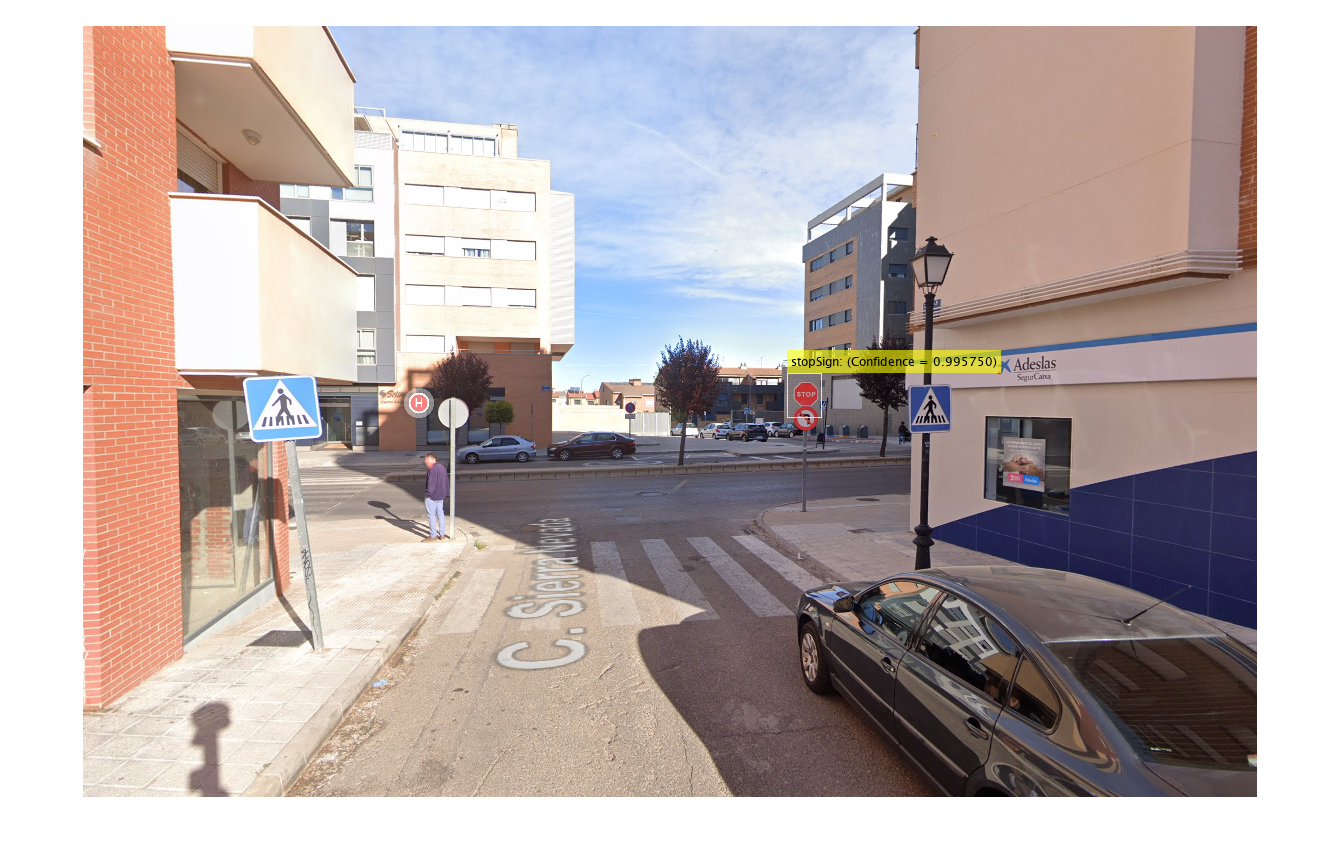

testImage = imread('stop.png');
[bboxes, score, label] = detect(rcnn, testImage, 'MiniBatchSize', 128); 
[score, idx] = max(score);
bbox = bboxes(idx, :);
annotation = sprintf('%s: (Confidence = %f)', label(idx), score);
outputImage = insertObjectAnnotation(testImage, 'rectangle', bbox, annotation);
figure; 
imshow(outputImage); 